
close all
clear all
colors=npg(10); % Ten basic colors 
tpi = 2*pi;

maindir='\\Artemis-pc\e\Data\2025-01-14\Abs-1241\';   % 相位数据
main_dir_0=maindir;
load([maindir,'\population.mat']);
%load([maindir,'\comagnetometer.mat']);   % 2024.12.20及以后
%load([maindir,'\negative_mag.mat']);   % 2024.12.16及以前

maindir='\\Artemis-pc\e\Data\2024-04-21\Abs-917\';   % 周期数
tau_s = 10;   % 进动秒数
tau_ms = 141.43;   % 进动毫秒数
load([maindir,'\cycle.mat']);
%load([maindir,'\cycle',num2str(tau_s),'s.mat']);

maindir='\\Artemis-pc\e\Data\2025-01-14\Abs-1141\';   % 对比度
load([maindir,'\FitResult.mat']);

%%%%                        %%%%
%%% ！！注意是否舍弃异常组 ！! %%%
%%%%                        %%%%

plot_allan = 0;
plot_sensitivity = 0;
plot_Histogram = 0;


if plot_allan == 1
    tau_single = 26.67+5;   % 单组时序时长(s)
    exclude_list = [];   % allan deviation的异常点
end




% ！！注意是否舍弃异常组 ！! %
delete_odd = 0;   % 原始数据是否存在异常点
if delete_odd == 1
    delete_num = [29];
end

% ！！注意修改 周期数 和 进动时间 ！！ %

a171 = amp2;   % 171 对比度
a171_sigma = a_sigma2;
%c171 = 0.046;
N171 = cycle171+4.5;

a173 = amp;   % 173 对比度
a173_sigma = a_sigma;
%c173 = 0.016;
N173 = cycle173+14;


% 进动时间，秒数在第一段修改 %
precession = tau_s*1e3 + tau_ms;   % 时序可设置的进动时间
wait1 = 10.1;   % ms
wait2 = 13.5;   % ms

tau171 = wait1+precession+wait2*3;
tau173 = precession+wait2;


if N171-floor(N171) == 0.25
    coefficient171 = 1;
elseif N171-floor(N171) == 0.75
    coefficient171 = -1;
end

if N173-floor(N173) == 0.25
    coefficient173 = 1;
elseif N173-floor(N173) == 0.75
    coefficient173 = -1;
end


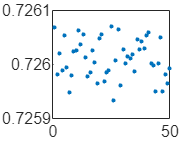


% 舍弃未稳定或异常组 %
if delete_odd == 1
    s1(delete_num) = []; s2(delete_num) = [];
    s3(delete_num) = []; s4(delete_num) = [];
%     s1(44) = []; s2(44) = [];
%     s3(44) = []; s4(44) = [];
%     s1(24) = []; s2(24) = [];
%     s3(24) = []; s4(24) = [];
%     s1([49,47]) = []; s2([49,47]) = [];
%     s3([49,47]) = []; s4([49,47]) = [];
end

% 进动曲线明显偏移零点对称 %
%dphase171 = real(asin(((s3-s4)./(s3+s4)-c171)/a171));
%dphase173 = real(asin(((s1-s2)./(s1+s2)-c173)/a173));

% 不考虑进动曲线 Offset 
%
dphase171_asin = real(asin(((s3-s4)./(s3+s4))/a171));
dphase173_asin = real(asin(((s1-s2)./(s1+s2))/a173));
dphase171 = ((s3-s4)./(s3+s4))/a171;
dphase173 = ((s1-s2)./(s1+s2))/a173;

dphase171_mean = mean(dphase171);
dphase173_mean = mean(dphase173);

parity171 = (s3-s4)./(s3+s4);
parity171_mean = mean(parity171);
parity171_std = std(parity171);
parity173 = (s1-s2)./(s1+s2);
parity173_mean = mean(parity173);
parity173_std = std(parity173);

dphase171_std = sqrt((parity171_std/a171)^2+(parity171_mean*a171_sigma/a171^2)^2);
dphase173_std = sqrt((parity173_std/a173)^2+(parity173_mean*a173_sigma/a173^2)^2);

% Yb-171 %
% 把S_z当成相位 %
phase171 = tpi*N171+coefficient171*dphase171;
f171 = phase171./(tau171*1e-3)/tpi;   % frequency Hz
f171mean = mean(f171);

% 用S_z反三角计算相位 %
phase171_asin = tpi*N171+coefficient171*dphase171_asin;
f171_asin = phase171_asin./(tau171*1e-3)/tpi;   % frequency Hz
f171mean_asin = mean(f171_asin);

% 提前平均 %
f171mean2 = mean((tpi*N171+coefficient171*dphase171_mean)./(tau171*1e-3)/tpi);

df171 = dphase171_std/(tau171*1e-3)/sqrt(length(f171)-1)/tpi;


% Yb-173 %
% 把S_z当成相位 %
phase173 = tpi*N173+coefficient173*dphase173;
f173 = phase173./(tau173*1e-3)/tpi;   % frequency Hz
f173mean = mean(f173);

% 用S_z反三角计算相位 %
phase173_asin = tpi*N173+coefficient173*dphase173_asin;
f173_asin = phase173_asin./(tau173*1e-3)/tpi;   % frequency Hz
f173mean_asin = mean(f173_asin);

% 提前平均 %
f173mean2 = mean((tpi*N173+coefficient173*dphase173_mean)./(tau173*1e-3)/tpi);

df173 = dphase173_std/(tau173*1e-3)/sqrt(length(f173)-1)/tpi;


% 频率比 %
% 把S_z当成相位 %
R = f171./f173;
Rmean2 = f171mean2./f173mean2;
Rstd = sqrt((df171/f173mean)^2+(f171mean*df173/f173mean^2)^2);

plot(1:length(R),R,'.');

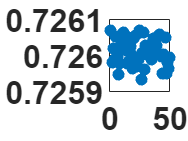



% 用S_z反三角计算相位 %
R_asin = f171_asin./f173_asin;
Rmean_asin = mean(R_asin);
Rmean2_asin = f171mean_asin./f173mean_asin;


delete_odd_posi = 0;    % 是否删除异常组

if delete_odd_posi == 1

    %R(1286) = [];R(1285) = [];R(1262) = [];
    R(1:30) = [];
    %R(71) = [];

%     for k = length(R):-1:1
%         if R(k)<0.7243
%             R(k) = [];
% 
%         end
%     end

end

f2 = figure;

plot(1:length(R),R,'.','MarkerSize',18);
set(gca,'FontSize',16,'FontName','Arial','FontWeight','bold');

Rmean = mean(R);
%Rstd = std(R)/sqrt(length(R)-1);



savefig(f2,[main_dir_0,'R.fig']);
saveas(f2,[main_dir_0,'R.png']);

## Allan Deviation

两种同位素分别

### Freq Allan


if plot_allan == 1


    
    %y_lim_low1 = 1e-4;

    [tau_k,allan_f_171,allan_f_std_171] = allan_deviation(f171);
    [tau_k,allan_f_173,allan_f_std_173] = allan_deviation(f173);

    tau = tau_single.*tau_k;

    h1 = figure; hold on;
    I11 = errorbar(tau,allan_f_171,allan_f_std_171,'.','Color','#C0321A',...
        'LineWidth',1.8,'MarkerSize',20,'CapSize',0);
    I12 = errorbar(tau,allan_f_173,allan_f_std_173,'.','Color','#8074C8',...
        'LineWidth',1.8,'MarkerSize',20,'CapSize',0);

     % 171设置 fittype 和选项。
    [xData11, yData11, weight11] = prepareCurveData(tau,allan_f_171,1./allan_f_std_171.^2);
    excludedPoints11 = excludedata( xData11, yData11, 'Indices', exclude_list );
    
    ft11 = fittype( 'a*x^(-1/2)', 'independent', 'x', 'dependent', 'y' );
    opts11 = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts11.Display = 'Off';
    opts11.Weights = weight11;
    opts11.Exclude = excludedPoints11;

    % 对171数据进行模型拟合。
    [fitresult11, gof] = fit(xData11, yData11, ft11, opts11);

    l11 = plot(fitresult11);
    l11.LineStyle = '--'
    l11.Color = '#FF7F50';
    l11.LineWidth = 2;

    % 173设置 fittype 和选项。
    [xData12, yData12, weight12] = prepareCurveData(tau,allan_f_173,1./allan_f_std_173.^2);
    excludedPoints12 = excludedata( xData12, yData12, 'Indices', exclude_list );

    ft12 = fittype( 'a*x^(-1/2)', 'independent', 'x', 'dependent', 'y' );
    opts12 = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts12.Display = 'Off';
    opts12.Weights = weight12;
    opts12.Exclude = excludedPoints12;

    % 对173数据进行模型拟合。
    [fitresult12, gof] = fit(xData12, yData12, ft12, opts12);

    l12 = plot(fitresult12);
    l12.LineStyle = '--'
    l12.Color = '#DDA0DD';
    l12.LineWidth = 2;

    legend('Yb-171','Yb-173','','','Location','southwest');

    xlim([min(tau) max(tau)]);
    %ylim([ y_lim_low1 max([ max(allan_freq_171) , max(allan_freq_173) ])*1.2 ]);

    xlabel('Interval s');
    ylabel('Allan Deviation ( Hz )');
    title('Frequency','FontName','Arial','FontWeight','bold');

    grid on;
    set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
        'XScale','log','YScale','log');
    set(h1,'Visible','on');



    savefig(h1,[main_dir_0,'dual_freq_allan.fig']);
    saveas(h1,[main_dir_0,'dual_freq_allan.png']);


## Freq Ratio Allan

    
    %y_lim_low2 = 2.5e-5;

    [tau_k,allan_R,allan_std_R] = allan_deviation(R);
    tau = tau_single.*tau_k;

    h2 = figure; hold on;
    I2 = errorbar(tau,allan_R,allan_std_R,'.');

    I2.CapSize = 0;
    I2.MarkerSize = 20;
    I2.LineWidth = 2;
    I2.Color = '#FF796C';

    % 设置 fittype 和选项。
    [xData2, yData2, weight2] = prepareCurveData(tau,allan_R,1./allan_std_R.^2);
    excludedPoints2 = excludedata( xData2, yData2, 'Indices', exclude_list );

    ft2 = fittype( 'a*x^(-1/2)', 'independent', 'x', 'dependent', 'y' );
    opts2 = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts2.Display = 'Off';
    opts2.Weights = weight2;
    opts2.Exclude = excludedPoints2;

    % 对数据进行模型拟合。
    [fitresult2, gof] = fit(xData2, yData2, ft2, opts2);

    l2 = plot(fitresult2);
    l2.LineStyle = '--'
    l2.Color = '#FF0000';
    l2.LineWidth = 2;

    xlim([min(tau) max(tau)]);
    %ylim([ y_lim_low2 max(allan_ratio)*1.1 ]);

    xlabel('Interval s');
    ylabel('Allan Deviation');
    title('Freq Ratio','FontName','Arial','FontWeight','bold');
    legend off;

    grid on;
    set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
        'XScale','log','YScale','log');
    set(h2,'Visible','on');



    savefig(h2,[main_dir_0,'ratio_allan.fig']);
    saveas(h2,[main_dir_0,'ratio_allan.png']);

end


## 灵敏度


if plot_sensitivity == 1

    %R(1:2) = [];

    group = floor(length(R))/8;

    for k = 1:group
        dR(4*k-3) = R(8*k-7)-R(8*k-6);
        dR(4*k-2) = R(8*k-4)-R(8*k-5);
        dR(4*k-1) = R(8*k-2)-R(8*k-3);
        dR(4*k) = R(4*k-1)-R(4*k-0);
    end

    dX = real(dR*tpi*f173mean);   % omega Hz
    dXfreq = dX/tpi;

    dRmean = mean(dR);
    dRstd = std(dR)/sqrt(length(dR)-1);

    dXmean = mean(dX);
    dXfreq_mean = mean(dXfreq);
    dXstd = real(tpi*sqrt(dRstd^2*f173mean^2+dRmean^2*df173^2));
    dXfreq_std = dXstd/tpi;

    l1 = plot(1:length(dR),dR,'.','MarkerSize',16,'Color',colors(1,:));
    set(gca,'FontSize',16,'FontName','Arial','FontWeight','bold');

end



if plot_Histogram == 1

    for k = 1:floor(length(dR)/32)
        dRbin(k) = mean(dR(10*k-9:10*k));
        dRbin_std(k) = std(dR(10*k-9:10*k))/sqrt(31);
    end

    I1 = errorbar(1:length(dRbin),dRbin,dRbin_std,'.','Color',colors(2,:), ...
        'MarkerSize',16,'LineWidth',1.8,'CapSize',0);
    set(gca,'FontSize',16,'FontName','Arial','FontWeight','bold');

    f1 = figure;
    h1 = histogram(dR);
    set(gca,'FontSize',16,'FontName','Arial','FontWeight','bold');
    grid on;
    %xlim([-5e-4 5e-4]);

    xlabel('\DeltaR');
    title('Histogram','FontName','Arial','FontWeight','bold');

    %set(gcf,'Visible','on');

    %savefig(f1,[main_dir_0,'pmag_dR_Histogram.fig']);
    %saveas(f1,[main_dir_0,'pmag_dR_Histogram.png']);

    savefig(f1,[main_dir_0,'nmag_dR_Histogram_all.fig']);
    saveas(f1,[main_dir_0,'nmag_dR_Histogram_all.png']);

end



%save([main_dir_0,'\positive_mag.mat']);
%pmag = load([maindir,'\positive_mag.mat']);

save([main_dir_0,'\comagnetometer.mat']);   % 2024.12.20及以后
%save([main_dir_0,'\negative_mag.mat']);   % 2024.12.16及以前


## Function

function [tau_k,deviation,allan_std] = allan_deviation(phase)

expon = log10(length(phase)/2);
k_list = floor(10.^[0:expon/30:expon]);

for k = length(k_list)-1:-1:1
    if k_list(k) == k_list(k+1)
        k_list(k+1) = [];
    end
end

for k = 1:length(k_list)

    N = floor(length(phase)/k_list(k));
    var_total = 0;

    for m = 1:N-1
        y_m1 = mean(phase((m-1)*k_list(k)+1:m*k_list(k)));
        y_m2 = mean(phase(m*k_list(k)+1:(m+1)*k_list(k)));
        var1(m) = (y_m2-y_m1).^2;
        var_total = var_total+var1(m);
    end

    tau_k(k) = k_list(k);
    deviation(k) = sqrt(var_total/(N-1)/2);
    allan_std(k) = deviation(k)/sqrt(N+1);

end

end
